#### Exemplo 02 - Symbolic Math

syms R C L

p = roots([L*C R*C 1])

$$p = \left(\begin{array}{c} -\frac{0.5000\,\left(R+\sqrt{-\frac{4\,L-C\,R^{2}}{C}}\right)}{L}\\ -\frac{0.5000\,\left(R-\sqrt{-\frac{4\,L-C\,R^{2}}{C}}\right)}{L} \end{array}\right)$$

clear R C L
syms R C L t Vc I0 real
syms ic(t)

id=diff(ic,t);
id2=diff(ic,t,2);

odei = L*C*id2 + R*C*id + ic == 0

$$odei(t) = C\,L\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{ic}\left(t\right)+C\,R\,\frac{\partial }{\partial t}\mathrm{ic}\left(t\right)+\mathrm{ic}\left(t\right)=0$$

condi1 = ic(0) == I0

$$condi1 = \mathrm{ic}\left(0\right)=I_{0}$$

condi2 = id(0) == -Vc/L

$$condi2 = \left({\left(\frac{\partial }{\partial t}\mathrm{ic}\left(t\right)\right)|}_{t=0}\right)=-\frac{\mathrm{Vc}}{L}$$

cond = [condi1, condi2];

i_sol = dsolve(odei,cond);
i_sol = simplify(i_sol)

$$i\_sol = \begin{array}{l} \frac{0.5000\,{\mathrm{e}}^{-\frac{0.5000\,t\,\left(\sqrt{\sigma_{1}}+C\,R\right)}{C\,L}}\,\left(I_{0}\,\sqrt{\sigma_{1}}+2\,C\,\mathrm{Vc}-C\,I_{0}\,R\right)}{{\sigma_{1}}^{0.5000}}+\frac{0.5000\,{\mathrm{e}}^{\frac{0.5000\,t\,\left(\sqrt{\sigma_{1}}-C\,R\right)}{C\,L}}\,\left(I_{0}\,\sqrt{\sigma_{1}}-2\,C\,\mathrm{Vc}+C\,I_{0}\,R\right)}{{\sigma_{1}}^{0.5000}}\\ \mathrm{where}\\ \sigma_{1}=C^{2}\,R^{2}-4\,C\,L \end{array}$$

% numerico
Rvalue = 0.01;
Lvalue = 0.5;
Cvalue = 0.5;
Vcvalue = 3;
I0value = 0.1;

p = roots([Lvalue*Cvalue Rvalue*Cvalue 1])

p =   -0.0100 + 2.0000i
  -0.0100 - 2.0000i



i_sol_n = subs(i_sol,{R,L,C},{Rvalue,Lvalue,Cvalue});
i_sol_n = subs(i_sol_n,{Vc,I0},{Vcvalue,I0value});
i_sol_n = simplify(i_sol_n)

$$i\_sol\_n = {\mathrm{e}}^{t\,\left(-0.0100-2.0000\,\mathrm{i}\right)}\,\left(0.0500-1.4998\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\left(-0.0100+2.0000\,\mathrm{i}\right)}\,\left(0.0500+1.4998\,\mathrm{i}\right)$$

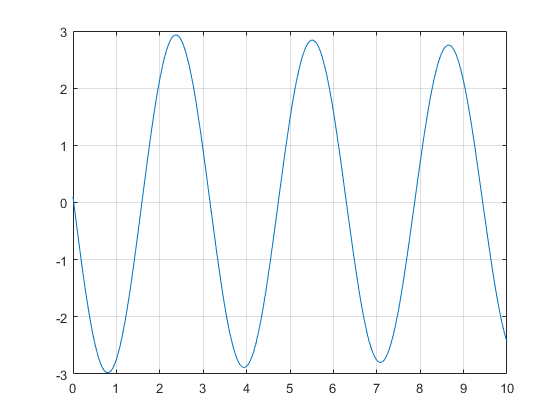


fplot(i_sol_n,[0 10])
grid on